# Cell segmentation test

% Input

%dapi_path = '../../Data/seg_test/dapi.tif';
nissl_path = '../../Data/BZ14_control/nissl/2base_BZ14_nissl_decon_ch01.tif';
output_path = '../../Data/seg_test/output';
%mask_path = '../../Data/seg_test/output/dapi_watershed_d2_8bit_mask.tif';

%dapi = new_LoadMultipageTiff(dapi_path, 'uint8', false);
nissl = new_LoadMultipageTiff(nissl_path, 'uint8', false);
%seg_mask = new_LoadMultipageTiff(mask_path, 'uint8', false);

## Gaussian Blur

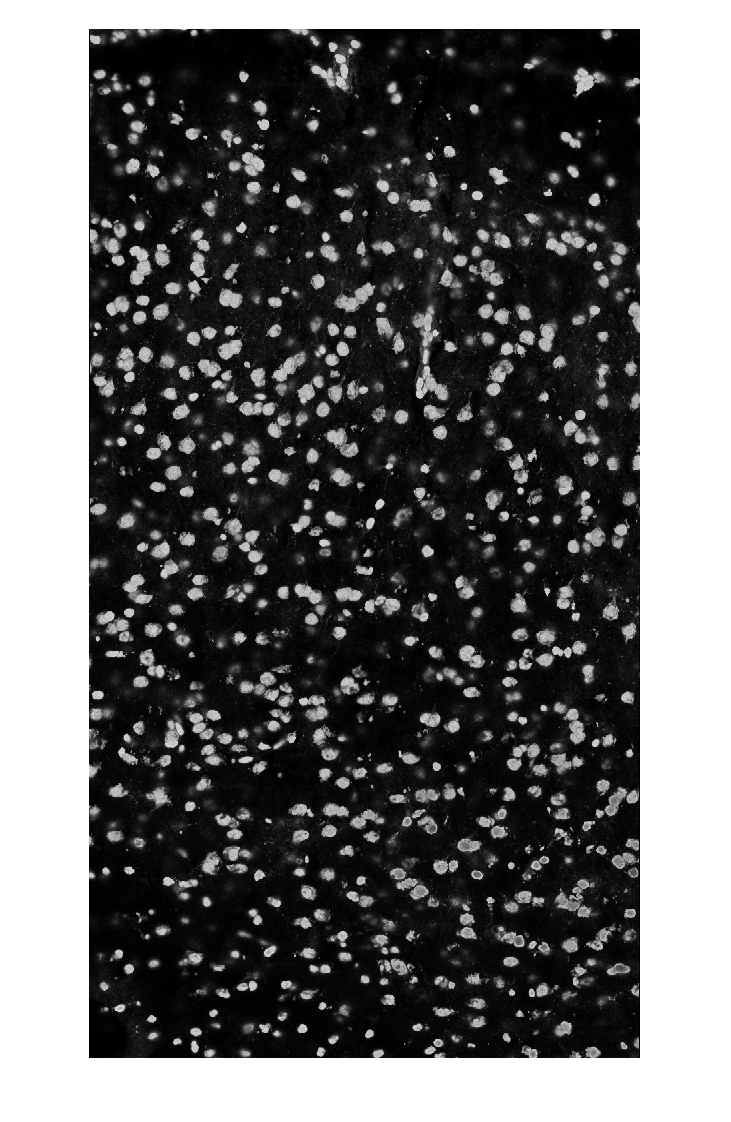

% Gaussian blur 3D
gaussian_3d = fspecial3('gaussian', [3 3 1], [2 2 1]);
%dapi_blur = imfilter(dapi, gaussian_3d); 
nissl_blur = imfilter(nissl, gaussian_3d); 

figure
%imshowpair(dapi_blur(:,:,1), nissl_blur(:,:,1), 'montage')
imshow(nissl_blur(:,:,1))

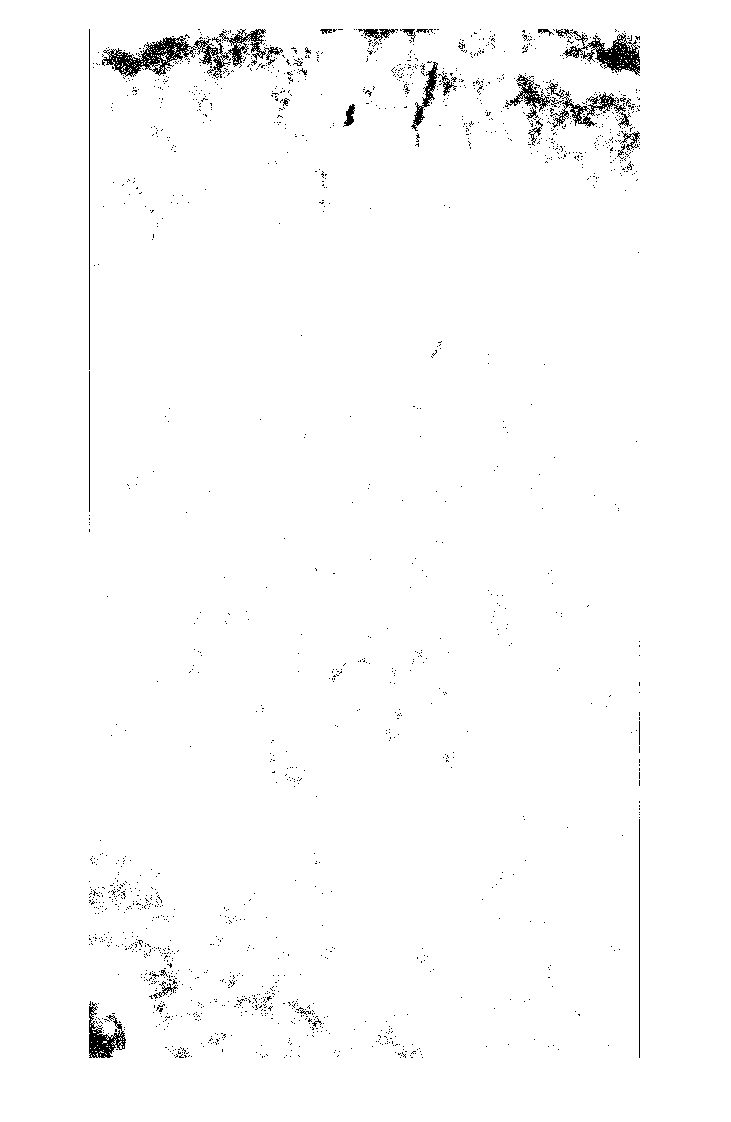

% Gaussian blur 2D
gaussian_2d = fspecial('gaussian', [3 3], 0.5);

% dapi_blur = zeros(size(dapi));
% for z=1:size(dapi,3)
%     curr_slice = dapi(:,:,z);
%     curr_blur = imfilter(curr_slice, gaussian_2d);
%     dapi_blur(:,:,z) = curr_blur;
% end

nissl_blur = zeros(size(nissl));
for z=1:size(nissl,3)
    curr_slice = nissl(:,:,z);
    curr_blur = imfilter(curr_slice, gaussian_2d);
    nissl_blur(:,:,z) = curr_blur;
end

figure
%imshowpair(dapi_blur(:,:,1), nissl_blur(:,:,1), 'montage')
imshow(nissl_blur(:,:,1))

## Thresholding - Binarization

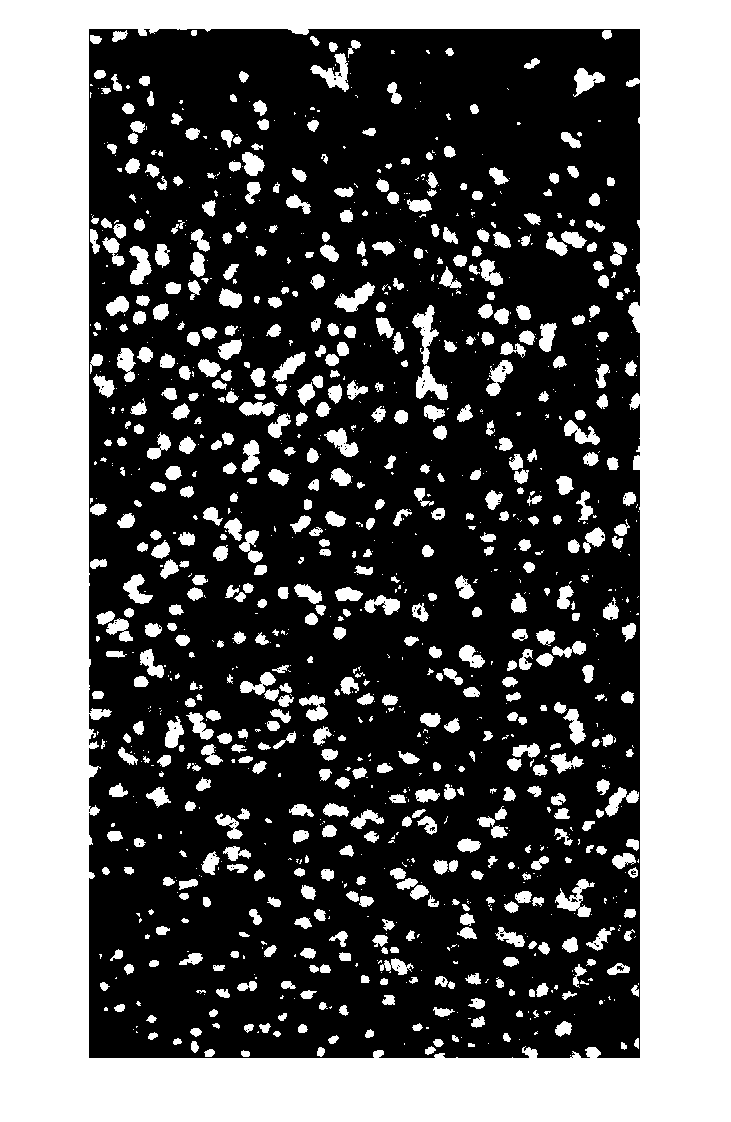

%dapi_bw = imbinarize(dapi_blur);
nissl_bw = imbinarize(nissl_blur);

figure
% imshowpair(dapi_bw(:,:,1), nissl_bw(:,:,1), 'montage')
imshow(nissl_bw(:,:,1))

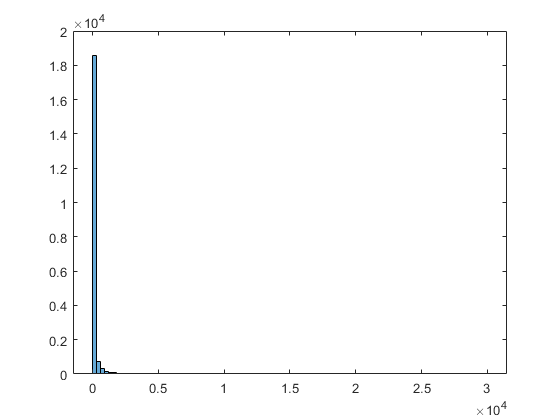


% dapi_bw_stats = regionprops3(dapi_bw, 'Volume');
nissl_bw_stats = regionprops3(nissl_bw, 'Volume');

% figure
% histogram(dapi_bw_stats.Volume, 100, 'BinLimits', [1,30000])

figure
histogram(nissl_bw_stats.Volume, 100, 'BinLimits', [1,30000])

## Morphology operation

se = strel('disk', 10);

%dapi_bw_close = imclose(dapi_bw, se);
nissl_bw_close = imclose(nissl_bw, se);

figure
% imshowpair(dapi_bw_close(:,:,1), nissl_bw_close(:,:,1), 'montage')
imshow(nissl_bw_close(:,:,1))

## Fill the holes

dapi_bw_fill = imfill(dapi_bw, 26, 'holes');
nissl_bw_fill = imfill(nissl_bw, 26, 'holes');

figure
imshowpair(dapi_bw_fill(:,:,1), nissl_bw_fill(:,:,1), 'montage')

## Remove small object

dapi_bw_big = bwareaopen(dapi_bw_close, 500, 6);
nissl_bw_big = bwareaopen(nissl_bw_close, 500, 6);

figure
imshowpair(dapi_bw_big(:,:,1), nissl_bw_big(:,:,1), 'montage')

dapi_bw_stats = regionprops3(dapi_bw_big, 'Volume');
nissl_bw_stats = regionprops3(nissl_bw_big, 'Volume');

figure
histogram(dapi_bw_stats.Volume, 100, 'BinLimits', [1,30000])

figure
histogram(nissl_bw_stats.Volume, 100, 'BinLimits', [1,30000])


D = bwdist(~dapi_bw_big(:,:,1), "euclidean");
imshow(D(:,:,1),[])
title('Distance Transform of Binary Image')

D = -D;

L = watershed(D, 6);
L(~dapi_bw_big(:,:,1)) = 0;

rgb = label2rgb(L(:,:,1),'jet',[.5 .5 .5]);
imshow(rgb)
title('Watershed Transform')


seg_mask_filter = bwareaopen(seg_mask, 20000, 6);
mask_label = bwlabeln(seg_mask_filter, 6);
mask_stats = regionprops3(mask_label, 'Volume');
histogram(mask_stats.Volume)

figure
imshow(label2rgb(mask_label(:,:,1), 'spring', 'k', 'shuffle'))

fname = fullfile(output_path, 'seg_mask_matlab.tif');
if exist(fname, 'file') == 2
    delete(fname);
end
for z=1:size(mask_label,3)        
    imwrite(mask_label(:,:,z), fname, 'writemode', 'append');        
end